clc; clear; close all;

load('higherd.mat')
higher_patch = C2_fcont_patch;

load('lowerd.mat')
lower_patch = C2_fcont_patch;

figure;
[XI,ETA] = higher_patch.xi_eta_mesh()

XI =     -1.350000000000000e+00    -1.300000000000000e+00    -1.250000000000000e+00    -1.200000000000000e+00    -1.150000000000000e+00    -1.100000000000000e+00    -1.050000000000000e+00    -1.000000000000000e+00    -9.500000000000001e-01    -9.000000000000000e-01    -8.500000000000001e-01    -8.000000000000000e-01    -7.500000000000000e-01    -7.000000000000001e-01    -6.500000000000001e-01    -6.000000000000001e-01    -5.500000000000000e-01    -5.000000000000000e-01    -4.500000000000000e-01    -4.000000000000001e-01    -3.500000000000001e-01    -3.000000000000000e-01    -2.500000000000000e-01    -2.000000000000000e-01    -1.499999999999999e-01    -1.000000000000001e-01    -5.000000000000004e-02                         0     4.999999999999982e-02     1.000000000000001e-01     1.499999999999999e-01     2.000000000000002e-01     2.500000000000000e-01     2.999999999999998e-01     3.500000000000001e-01     3.999999999999999e-01     4.500000000000002e-01     5.000000000000000e-01     5.

ETA =     -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1.350000000000000e+00    -1

useless_msk = XI >= 0.39 & ETA >= 0.39;
%exterior_msk = XI <= 0 | ETA <= 0
% exterior_msk = logical(ones(size(XI)))
exterior_msk = (XI >= 0 & ETA >= 0) & (~useless_msk)

exterior_msk = 48×48 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


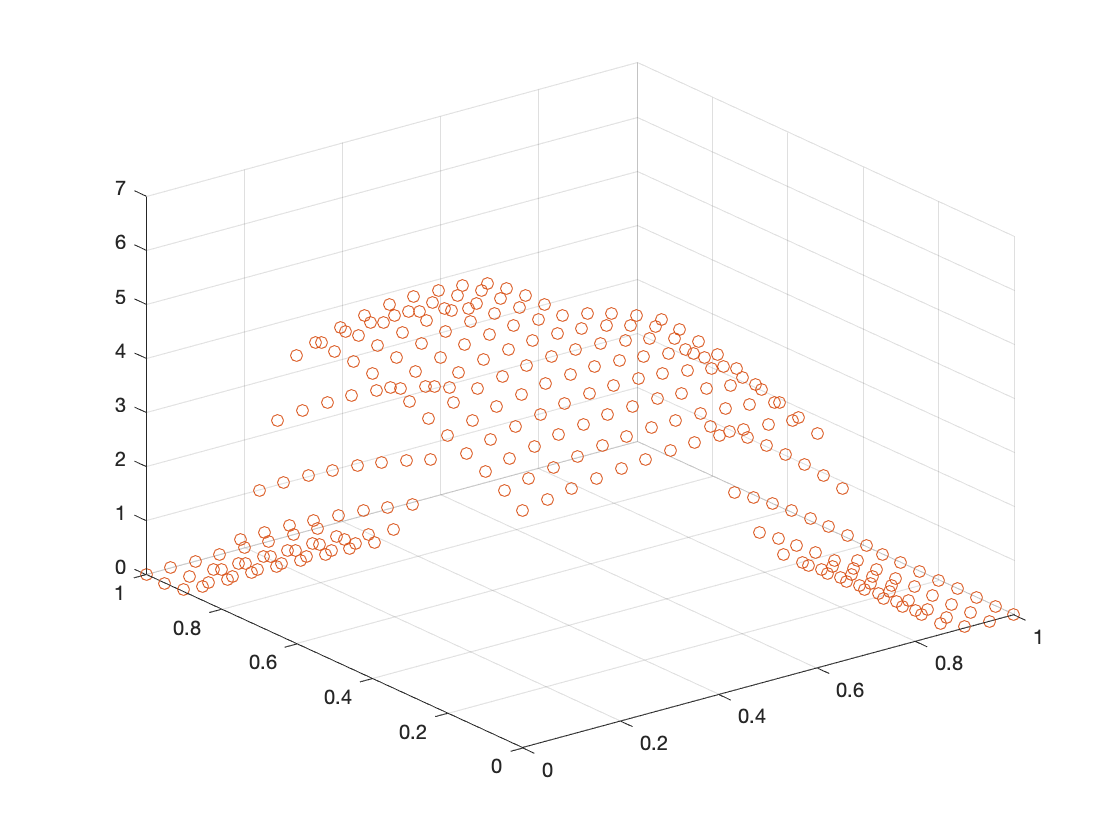

scatter3(XI(exterior_msk), ETA(exterior_msk), higher_patch.f_XY(exterior_msk))
hold on;
scatter3(XI(exterior_msk), ETA(exterior_msk), lower_patch.f_XY(exterior_msk))

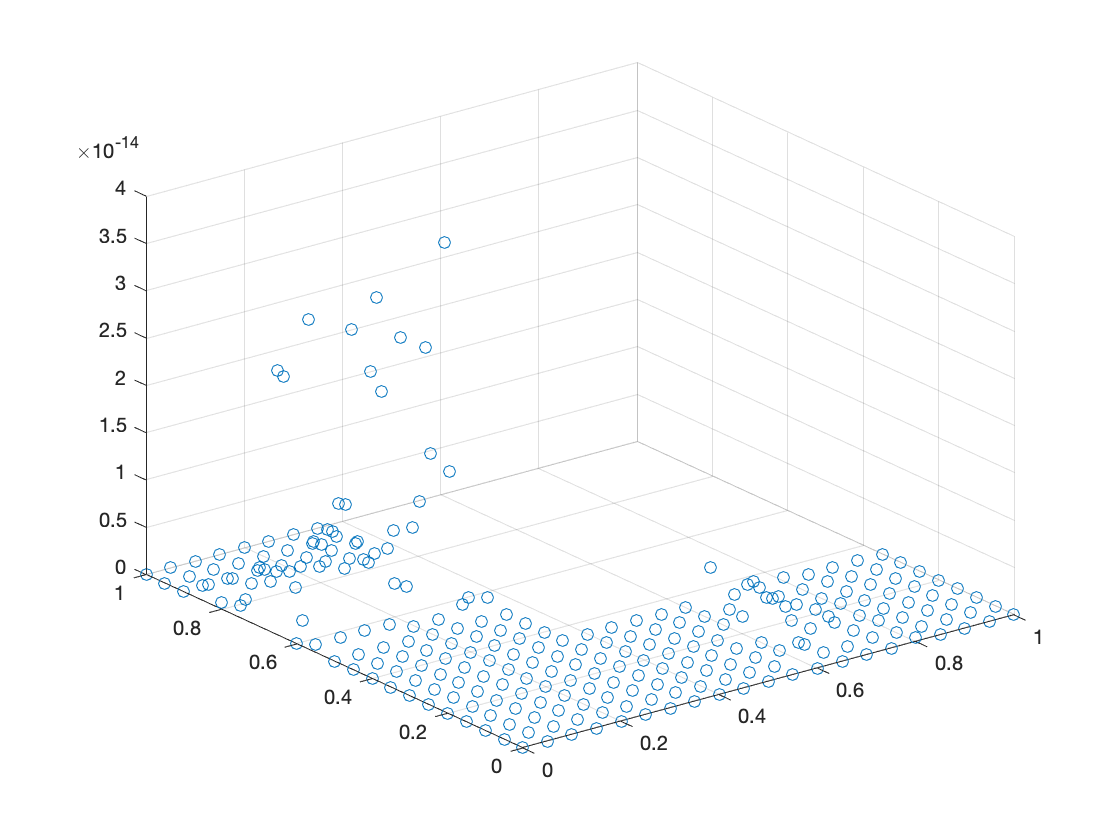


figure;
scatter3(XI(exterior_msk), ETA(exterior_msk), abs(higher_patch.f_XY(exterior_msk) - lower_patch.f_XY(exterior_msk)))

max(abs(higher_patch.f_XY(exterior_msk) - lower_patch.f_XY(exterior_msk)))

ans =      3.819167204710538e-14
